close all;
clc        % clear commmand window
clear      % clear MATLAB workspace

## Set up robot control system (code that runs once)

img = imread('TestPool.png'); % load oval image 
grayimage = im2gray(img);       % convert to grayscale
bwimage = grayimage < 0.5;      % convert to black and white

SE = strel("disk",15);
map = imclose(bwimage, SE);
map = imcomplement(map);

% imshow(map)

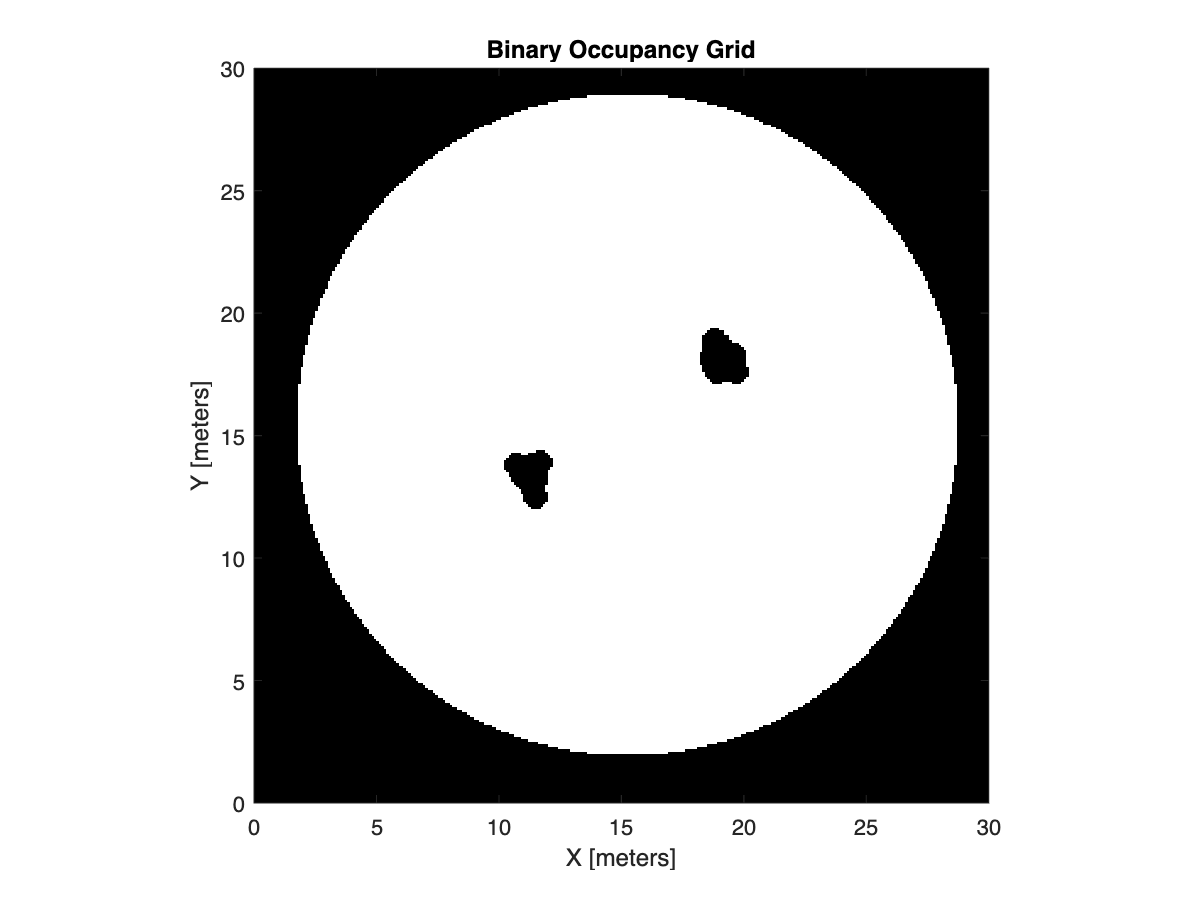


MapOfOval = binaryOccupancyMap(bwimage,10); % convert to a binary occupancy map in meters
show(MapOfOval);

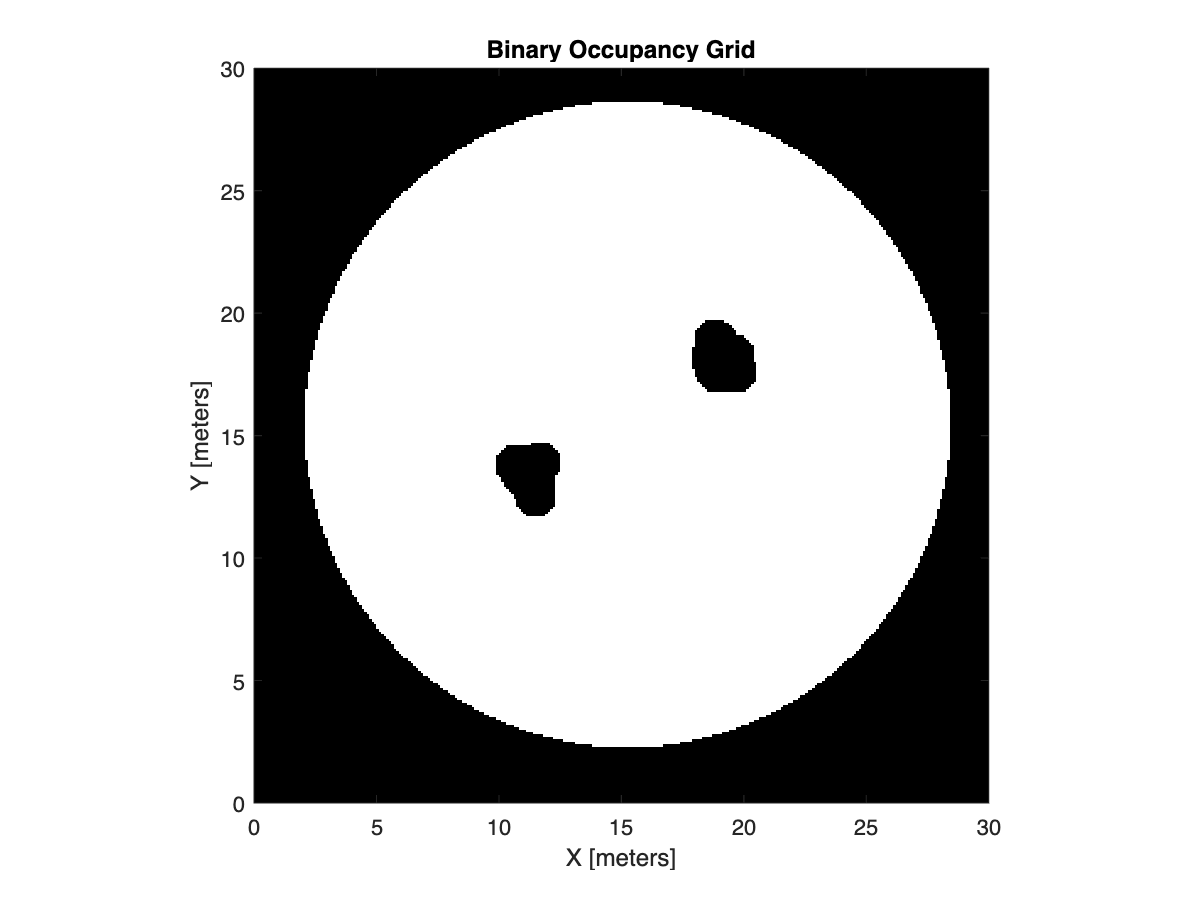

% Inflate the map wit the robot rober size, so robot can be treated as a
% point. Assume robot rober is a 0.25m long bow to stern
MapOfOvalInflated= copy(MapOfOval); % make a copy to save original data
inflate(MapOfOvalInflated,0.25); %dilate map to accomendate robot size
show(MapOfOvalInflated)

controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 2;
controller.MaxAngularVelocity = 3;

prm = robotics.PRM(MapOfOvalInflated);
prm.NumNodes = 100;
prm.ConnectionDistance = 10;

startLocation = [20.0 25.0];
endLocation = [15.0 5.0];
path = findpath(prm, startLocation, endLocation)

path =    20.0000   25.0000
   20.1988   24.2761
   17.4956   18.6202
   16.0740   15.1628
   14.5289    8.9981
   14.6281    4.6077
   15.0000    5.0000


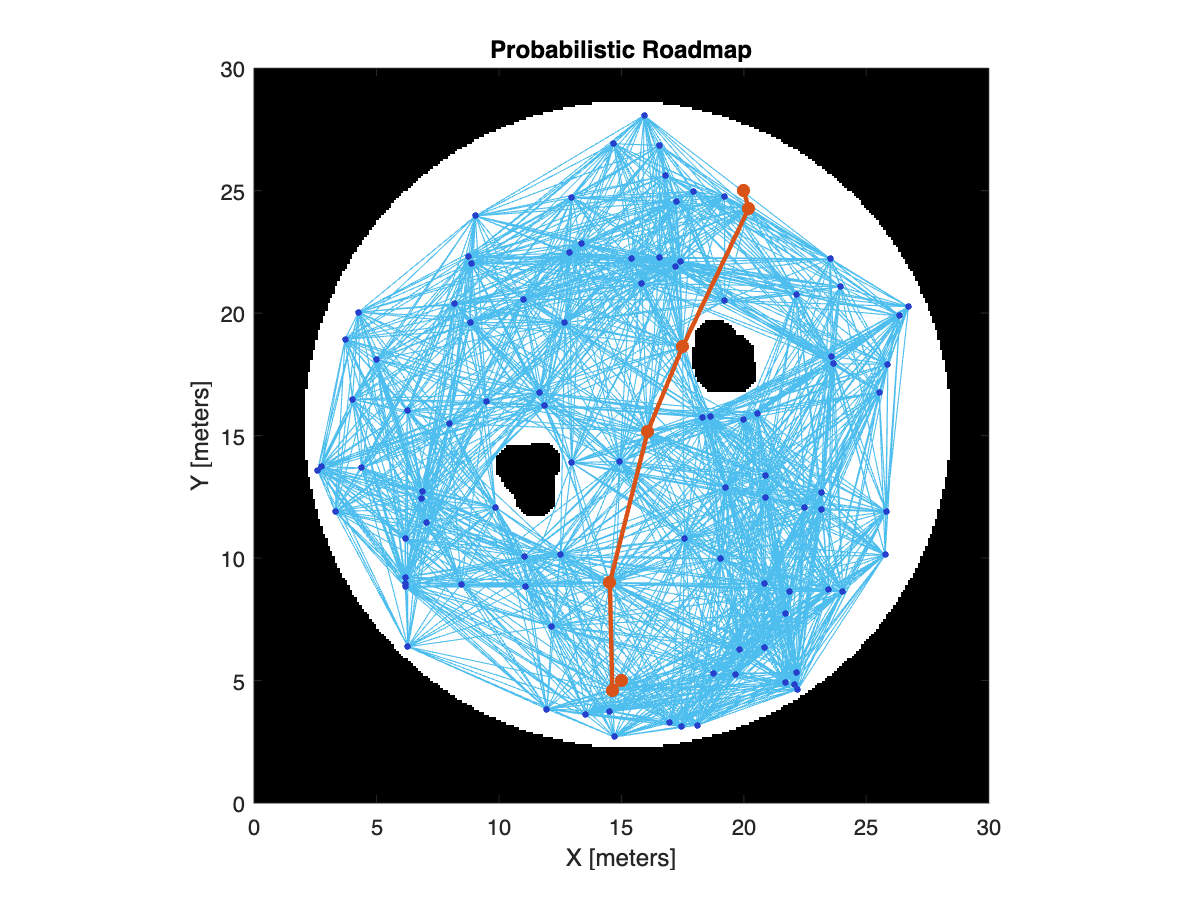

show(prm)

release(controller);
controller.Waypoints = path;

Error using controllerPurePursuit
Expected Waypoints to be one of these types:

double, single

Error in nav.algs.internal.PurePursuitBase/validateWaypoints (line 325)
            validateattributes(waypts, {'double', 'single'},...

Error in 

robotInitialLocation = path(1,:);

Unrecognized function or variable 'path'.

robotGoal = path(end,:);
initialOrientation = pi/2;
robotCurrentPose = [robotInitialLocation initialOrientation]';
distanceToGoal = norm(robotInitialLocation - robotGoal);
goalRadius = 0.1;

robot = differentialDriveKinematics('VehicleInputs','VehicleSpeedHeadingRate');

sampleTime = .1;
vizRate = rateControl(1/sampleTime);
reset(vizRate);

% Initialize the figure
figure

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    show(MapOfOvalInflated);
    hold all

    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, 'MeshFilePath', 'groundvehicle.stl', 'Parent', gca, "View","2D");
    light;
    xlim([0 27])
    ylim([0 26])
    
    waitfor(vizRate);
end

Unrecognized function or variable 'distanceToGoal'.